# Plotting LIDAR data in Global Frame

Objective:  This script will show you how to use both the the *range2xy * and *transform_points* functions to transform LIDAR data to plot it in the **global frame.** This script uses the the robot pose to transform the data from the sensor frame to the robot frame using transform_points and plot your results

Cheat Sheet: In this script, you will use the following functions and CreateRobot properties:

- CreateRobot.radius: Radius of the Create Robot 

- CreateRobot.angRangeLidar: Angular range of LIDAR sensor

- CreateRobot.rangeLidar: Linear range of LIDAR sensor

- CreateRobot.numPtsLidar: Number of points in LIDAR sensing range

- CreateRobot.angleArray: Array of LIDAR angles

- genLidar(CreateRobot): Generates a reading for the LIDAR sensor

For more information on these functions and properties, refer to the CreateRobot documentation 

help CreateRobot %in Command Window

  Creates definition of class, instances of which will include all
  properties and controls associated with a single CreateRobot robot

    Documentation for CreateRobot



Helper Functions used in this exercise:

- *plot_frames: *plots a data point both in the robot frame and the global frame.The robot is a black circle with a radius pointing in its positive x direction, and the data points are represented by red dots, which typically form a line. 

Exercise:

In the Simulator, press the Read Sensors button to get the CreateRobot object that represents the current state of the robot. You will use the object (named **robotObj**) in this script.

Complete the code below to;

- Initialize robot constraints based on the CreateRobot and sensor configuration. 

- Obtain the robot pose

- Read the LIDAR sensor

- Transform  the lidar sensor output to x-y cooridnates in sensor frame

- Transform the LIDAR from the sensor frame to the robot frame. 

- Transform the LIDAR data from robot frame to global frame

%1. Initialize robot constraints based on the CreateRobot and sensor configuration.

%Define the LIDAR pose based on the robot's radius in the robot reference frame
%Remember that the robot reference frame always defines the robot position at [0; 0; 0],
robotRadius = robotObj.radius; %Insert your code here
lidar_pose = [robotRadius;  0;  0];%Insert your code here

% Initialize, get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar;%Insert your code here
rangeLidar = robotObj.rangeLidar;%Insert your code here
numPtsLidar = robotObj.numPtsLidar;%Insert your code here
angleArray= robotObj.angleArray; %Insert your code here

% 2. Obtain the robot pose
% Read the current position of the robot from the overhead 
[x, y, th] = genOverhead(robotObj);%Insert your code here
robot_pose = [x; y; th];  %Insert your code here

% 3. Read the LIDAR sensor

% Get LIDAR data, this is a row vector with length = numPtsLid
distLidar= genLidar(robotObj,map);%Insert your code here


%4. Transform  the lidar sensor output to x-y cooridnates (in the sensor frame)
dataxy_sensor = range2xy(angleData, distLidar,rangeLidar); %Insert your code here

%5. Transform the xy coordinates from sensor frame to robot frame 
dataxy_robot = transform_points(lidar_pose,dataxy_sensor); %Insert your code here

%6. Transform the xy coordinates from robot frame to global frame 
dataxy_global = transform_points(robot_pose, dataxy_robot); %Insert your code here

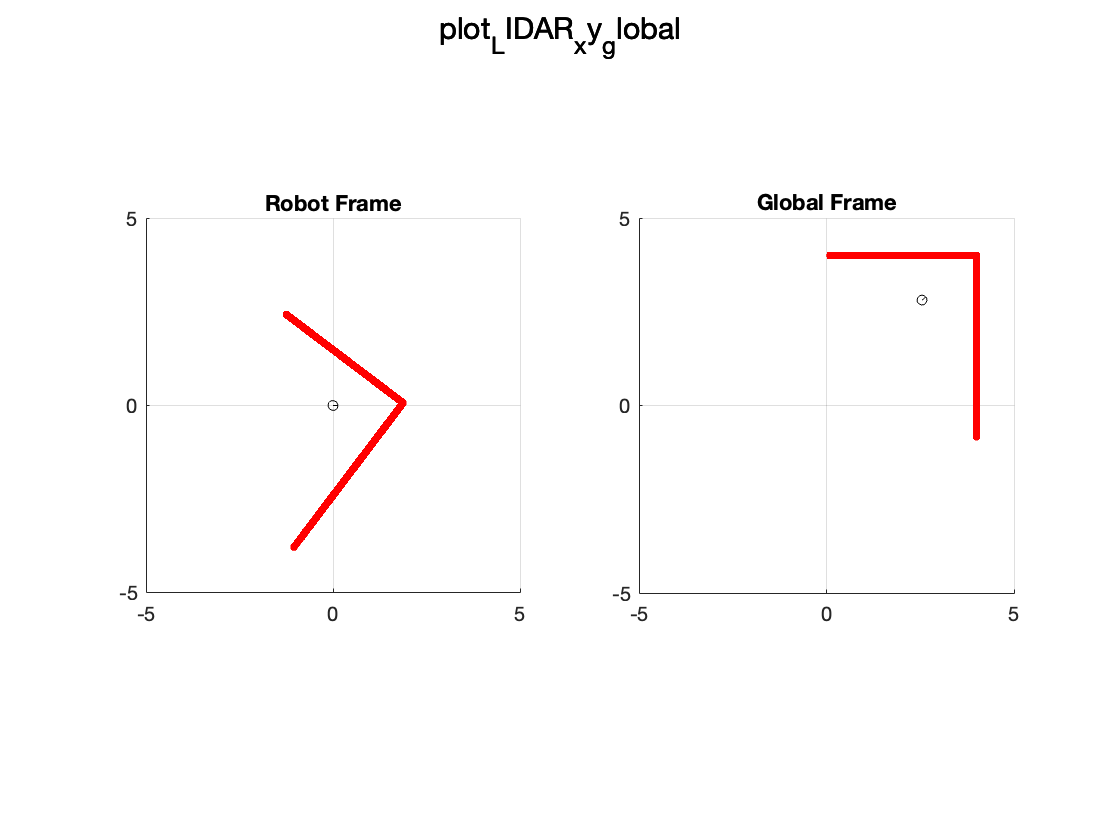

%Plot
plot_frames(robot_pose, dataxy_robot, dataxy_global, "plot LIDAR xy global");


Expected Results: Because you are plotting the LIDAR data in the **global frame**, you should see the sensor readings as you would see the map in the simulator. If the implemenation is correct, robot and global frame plots should look the same with respect to the robot heading. 

Check your Comprehension:

How do the two plots differ? Given the orientation of the robot, does the difference between the robot and global frame make sense? Move the robot around the map facing different obstacles and compare the plots. 